## Apply basic signal processing on GW data

First, we read in some GW data and look at time and Fourier domain plots. This will also read in ancillary parameters of the data such as the sampling frequency.


.           ..          .git        .gitignore  DETEST      DSP         GWDATA      LICENSE     MDC         NOISE       README.md   SIGNALS     

        4096



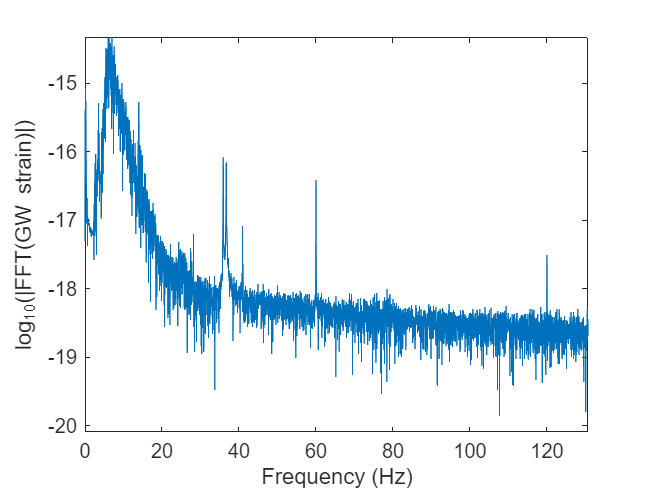

readgwoscdat;

Viewed in the time-domain, the noise is dominated by high spectral power at low frequencies. We can demonstrate this by plotting a low-pass filtered version of the data on top of the original data. Here, we will use the FILTFILT function that implements a zero-delay filter.

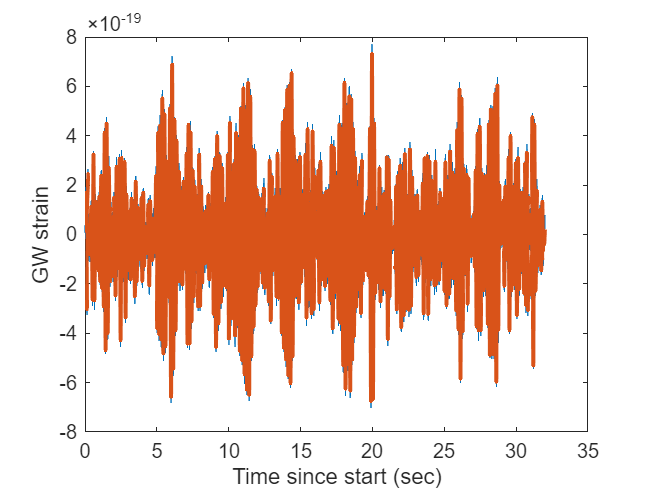

%Low-pass frequency cutoff
fLow = 30; %Hz
%Low-pass filter type is IIR: Butterworth filter
[b,a] = butter(5,fLow/(samplFreq/2));
%Zero-delay filtering
lpDataVec = filtfilt(b,a,dataVec);
lpDataFFT = fft(hann(nSamples).*lpDataVec);
%Plots
figure(tdFig);
hold on;
plot(timeVec,lpDataVec,'LineWidth',2.0);

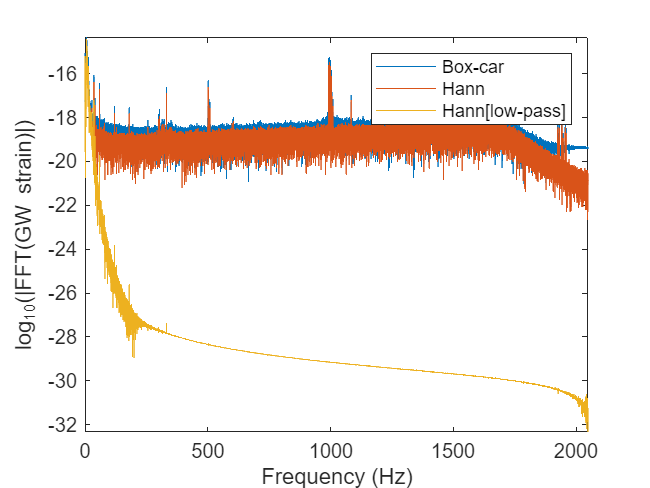


figure(pdFig);
hold on;
plot(posFreq,log10(abs(lpDataFFT(1:kNyq))));
legend('Box-car','Hann','Hann[low-pass]');

It's impossible to see any part of a GW signal whose spectrum lies in the interval dominated by the large low-frequency noise. The first step, therefore, is to suppress this part of the spectrum using a high-pass filter.

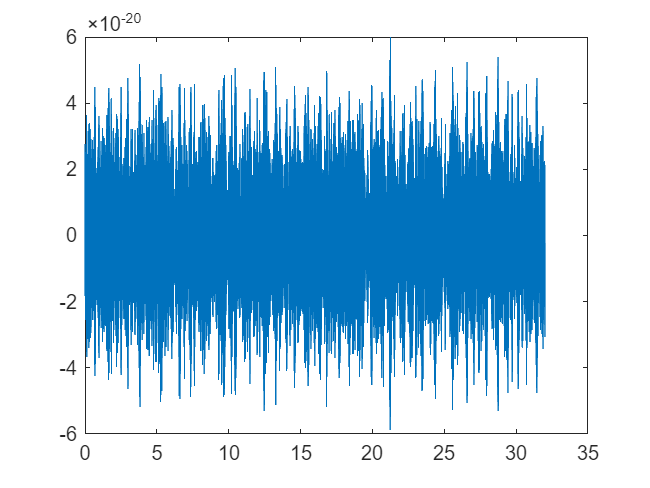

%high-pass frequency cutoff
fHi = 50;%Hz
%high-pass filter type is IIR: Butterworth filter
[bh,ah] = butter(5,fHi/(samplFreq/2),'high');
%Zero-delay filtering
hpDataVec = filtfilt(bh,ah,dataVec);
%Plots
figure;
plot(timeVec,hpDataVec);

  However, this still does not solve the problem because the spectrum of the data is also dominated by sharp narrow-band features called **lines**.

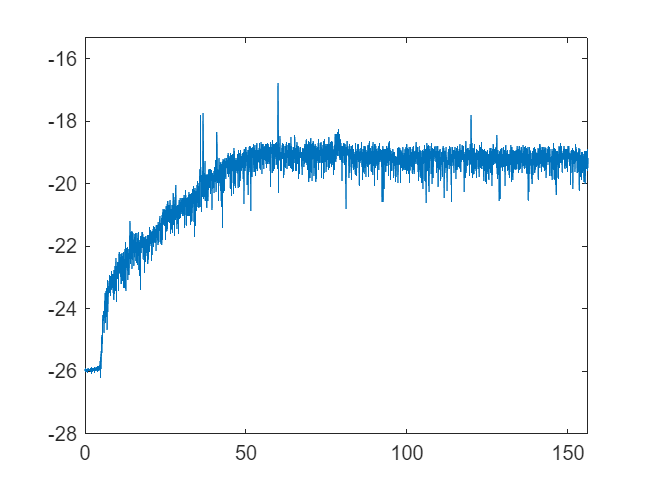

hpDataFFT = fft(hann(nSamples).*hpDataVec);
figure;
plot(posFreq,log10(abs(hpDataFFT(1:kNyq))));